# Basic Signal Analysis

Record the sentence: "She has a watch thin as a dime." using 44100 sample rate. Please try to enunciate clearly as if you are a BBC announcer. We will use this sentence in further work.

Put your code here:

close all,
samplerate = 44100;
recObj = audiorecorder(samplerate, 16, 1);
disp('Start speaking');

Start speaking


recordblocking(recObj, 5);
disp('End of recording. Playing back...');
play(recObj);

Window your recorded signal in the time domain. This means to remove noise or zeros at the start and end of the signal. You can do this by plotting your signal to see its time extent. You can zoom in to see where the signal starts and ends. You can then select a restricted portion of the signal which removes the rubbish at the start and end of the signal. You should also listen to the signal.

Put your code here:

y = getaudiodata(recObj);
plot(y);
title('Voice Recording');
new_y = y(90000:165000);
plot(new_y);

Save your time windowed signal as a wave file and upload with your lab solution.

Put your code here:

filename = 'lab2_voice_recording.wav'
audiowrite(filename, new_y, samplerate)


% this makes revisiting this task easier so we do not have to re-record everytime.
[new_y, samplerate] = audioread('lab2_voice_recording.wav');

## Filtering Signals

**FIR Filters**

Finite Impulse Response filters are finite sequences that correspond to the impulse response of some physical or theoretical system. Mathematically, they are described by a causal, stable sequence.

Filtering a signal with an FIR filter simulates the action of the physical or theoretical system. Let's demonstrate this. 

Consider the acoustic impulse response of a church. It could be measured using a log sine sweep or in the olden days it could be measured with a blank gun shot or the pop of a balloon.

Run the code below.

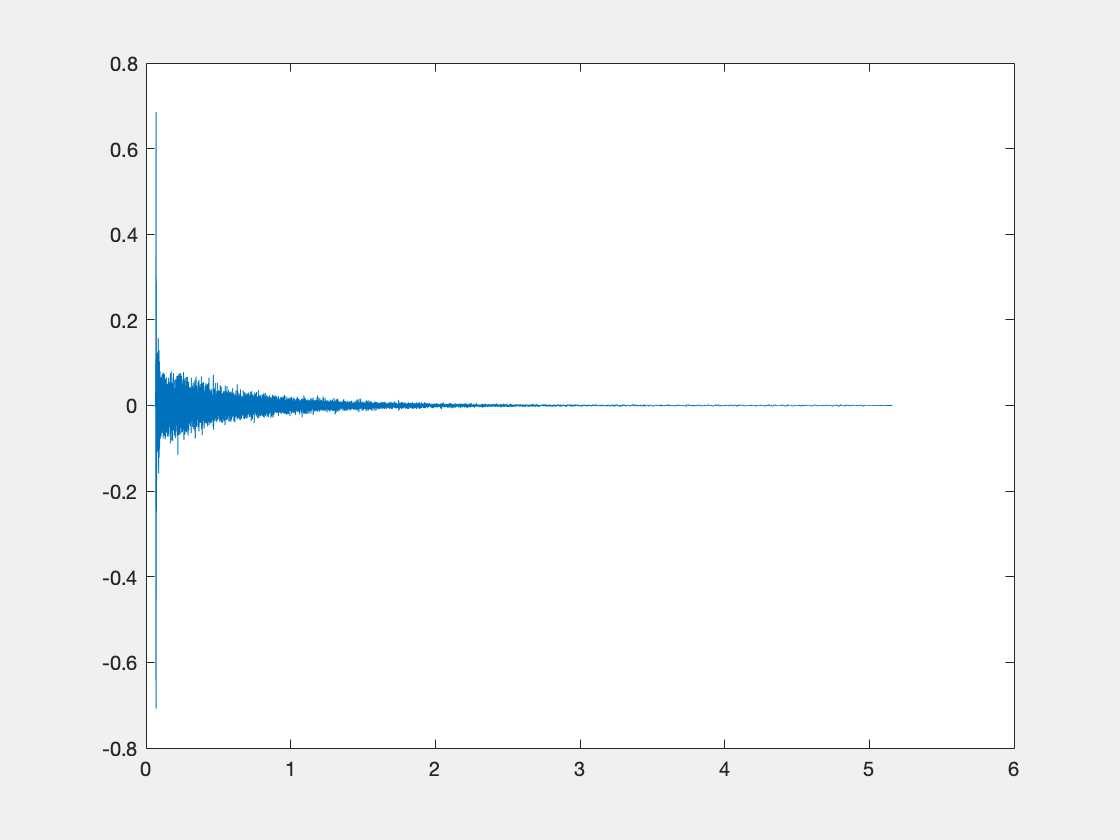

% churchIR = a, 
[churchIR, fsIR] = audioread('ChurchImpulseResponse-16-44p1-mono-5secs.wav');
soundsc(churchIR, fsIR)
fh = figure; set(gcf,'Visible','On')
tIR = (0:length(churchIR)-1).'/fsIR ;
plot(tIR,churchIR)

What did the impulse response sound like?

Put your answer here:

Answer: A gun shot.

Let's now filter our recorded sentence with the church impulse response. This will make it seem like the speech was recorded inside the church! 

Use the Matlab function filter to filter your recorded signal with the church impulse response.

Play the filtered audio signal. It should now sound as if it was recorded in a church!

Put your code here:

% filter(b, a, x) = filters the data in vector x with filter described by numerator
% coefficient b and denominator coefficient a.
filtered_y1 = filter(churchIR, 1, new_y);
sound(filtered_y1, samplerate);

Since we just introduced a room impulse response, we might as well speak a little bit about room acoustics. 

Sound waves in air travel at roughly 345 m/s. Shortly after the arrival of the direct sound, a series of semi-distinct reflections arrive from various reflecting surfaces (walls, floor and ceiling). These early reflections are defined to occur within 50 to 80 milliseconds. Early reflections are not heard as separate from the direct sounds and instead reinforce the direct sound. For a rapidly varying sound such as speech the limit is closer to 50 ms while for singing and music the limit is closer to 80 ms. In other words, the concept of the early reflections is related to sound perception.

Studies have shown (e.g., Leo Beranek, 1962) that a church or concert hall is considered intimate if the delay time between the direct and first reflected sound is less than 20 ms.

Reflections that arrive after the early reflections are typically lower in amplitude and closely spaced in time. These reflections are often referred to as the late reverberation or late reflections.

The reverberation time (RT60) is generally defined as the time for the reverberant sound to decrease by 60 dB from its original level and varies with frequency.

Let's play around with these ideas. First, we will plot the early reflection period.

Plot the early reflection period of the church impulse response.

Then, zero out the early reflections in the impulse response and re-filter the recorded sound with the modified church impulse response. Play the new audio signal. You should get the impression that the direct sound is somehow lessened.

Put your code here:

size(churchIR)

ans =       227497           1


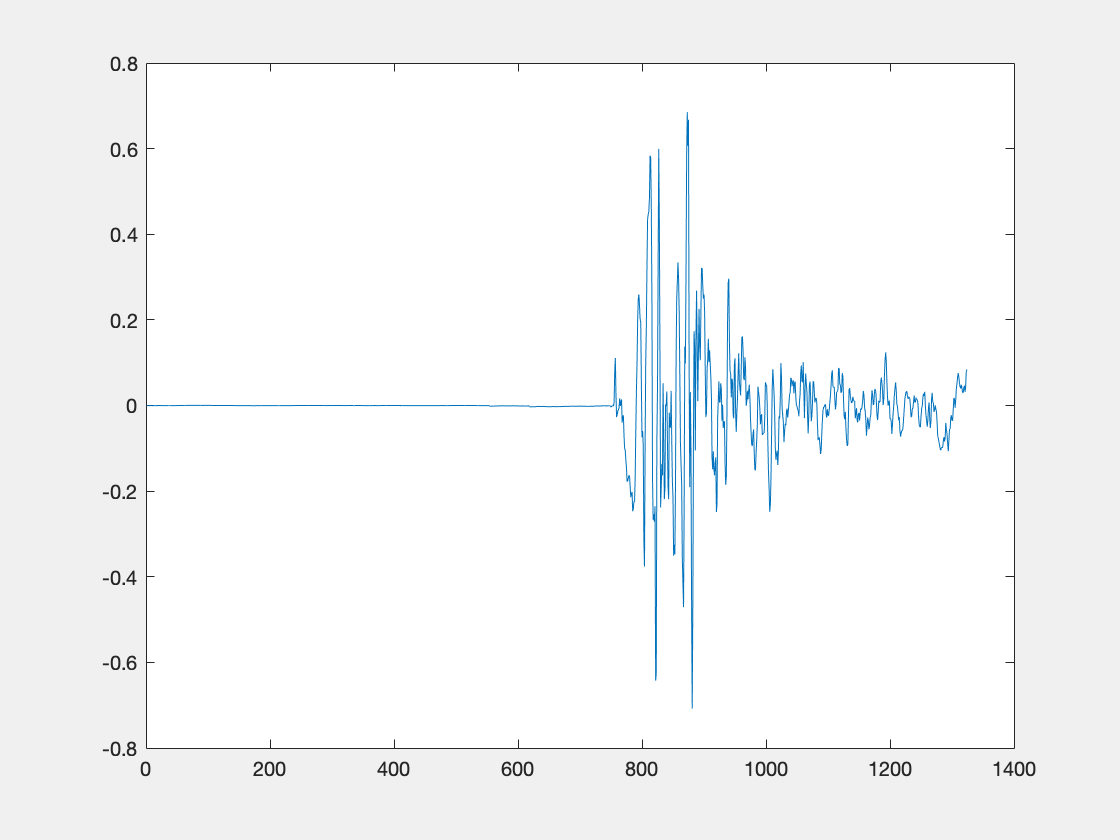

% Plot the early reflection period (50ms - 80ms)
plot(churchIR((50*10^(-3)*samplerate):(80*10^(-3)*samplerate)));

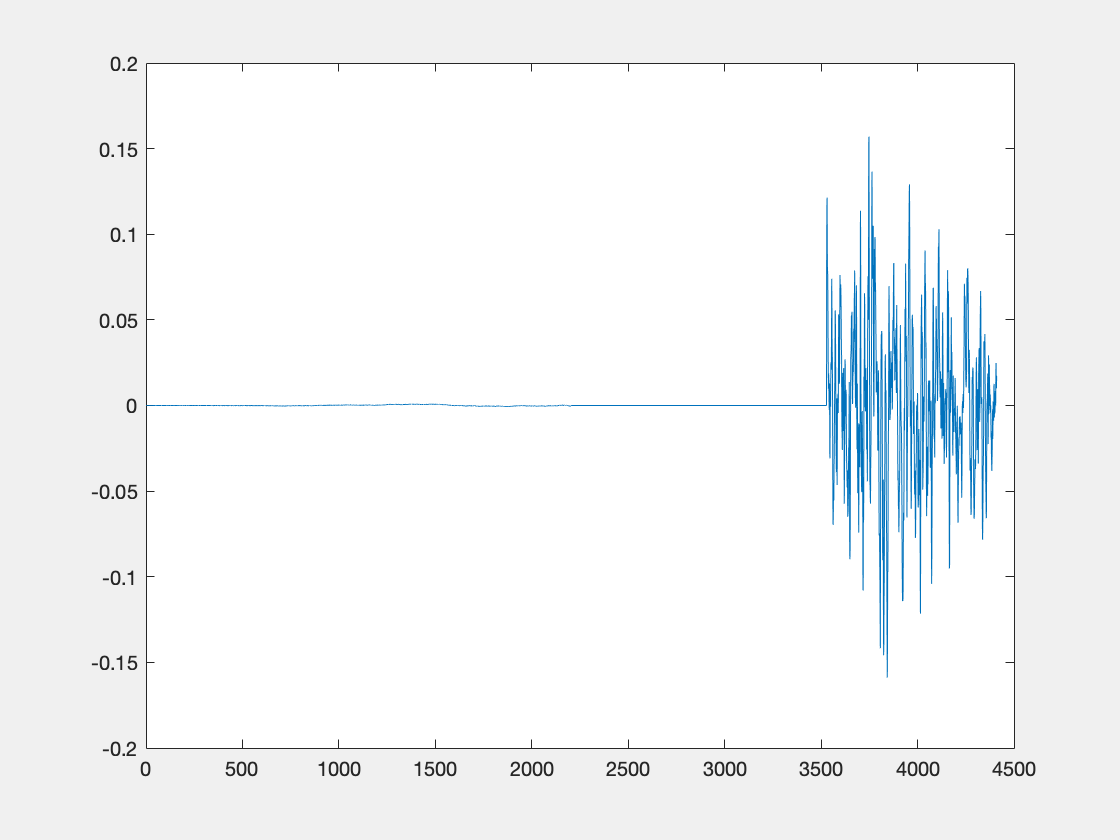

new_churchIR = churchIR;
% zero out values between 50ms and 80ms
new_churchIR((50*10^(-3)*samplerate):(80*10^(-3)*samplerate))=0;
% new_churchIR = [churchIR(0:50*10^(-3)*samplerate), zeros(1, 30*10^(-3)*samplerate), churchIR(80*10^(-3)*samplerate:end)];
plot(1:100*10^(-3)*samplerate, new_churchIR(1:100*10^(-3)*samplerate));

filtered_y2 = filter(new_churchIR, 1, new_y);
sound(filtered_y2, samplerate);

% change the x scale to time for both plots.

Repeat the above, but now keep the early reflections and remove the late reverberation. Re-filter the recorded sound, play the new audio signal. The reverberation should now be lessened.

Put your code here:

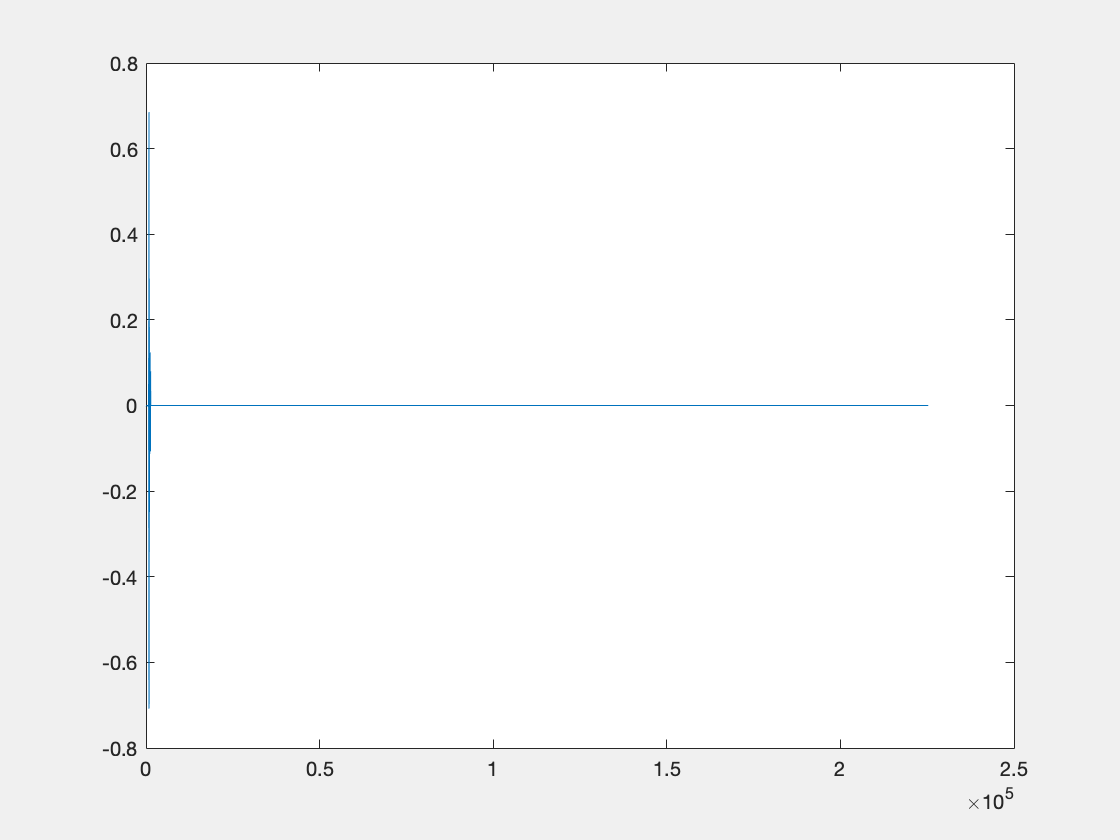

% The reverberation period assumed to be 80ms - end of impulse response
new_churchIR2 = churchIR;
% zero out values between 50ms and 80ms
new_churchIR2((80*10^(-3)*samplerate):end)=0;
% new_churchIR = [churchIR(0:50*10^(-3)*samplerate), zeros(1, 30*10^(-3)*samplerate), churchIR(80*10^(-3)*samplerate:end)];
plot(new_churchIR2(50*10^(-3)*samplerate:end));

filtered_y3 = filter(new_churchIR2, 1, new_y);
sound(filtered_y3, samplerate);

% change the x scale to time for both plots.

# Truncated Ideal Low-Pass Filter

Create an ideal truncated low-pass filter based on the following formula


$$H(e^{j\,\omega}) = \left\{\begin{array}{ll}
1\cdot e^{-j\,\alpha\,\omega}\text{,} & |\omega| \lt \omega_c \\
0\text{,} & \omega_c < |\omega| \le \pi
\end{array}$$


## Compute the Analytic Solution for the impulse response below:

Show your work using latex equations below.

Put work here:


$$h\left\lbrack n\right\rbrack =\frac{1}{2\pi }\int_{-w_c }^{w_c } e^{-\mathrm{jaw}} e^{\mathrm{jwn}} \;\mathrm{dw}=\frac{1}{2\pi }\int_{-w_c }^{w_c } e^{\mathrm{jw}\left(n-a\right)} \;\mathrm{dw}=\frac{1}{2\pi }\left\lbrack \frac{1}{j\left(n-a\right)}\right\rbrack \left\lbrack e^{{\mathrm{jw}}_c \left(n-a\right)} -e^{{-\mathrm{jw}}_c \left(n-a\right)} \right\rbrack$$



$$h\left\lbrack n\right\rbrack =\frac{1}{2\pi j\left(n-a\right)}$$

$$\left\lbrack e^{{\textrm{jw}}_c \left(n-a\right)} -e^{{-\textrm{jw}}_c \left(n-a\right)} \right\rbrack =\frac{\mathrm{sin}\left(w_{c\;} \left(n-a\right)\right)}{\pi \left(n-a\right)}$$


Determine and plot the truncated impulse response 


$$h[n] \ \text{for} \ 0 \le n < N-1$$


using N = 61, $\alpha = 30$. Choose $\omega_c$ so that the cut-off frequency is 1500 Hz, using 44100 sample rate.

Put your code here

fs = 44100;
n = (0:61);
% cutoff frequency of 1500Hz
omegac = (2*pi*1500);
a = 30;
xn = sin(omegac*(n-a)/fs)./(pi*(n-a));
size(n)

ans =      1    62


size(xn)

ans =      1    62


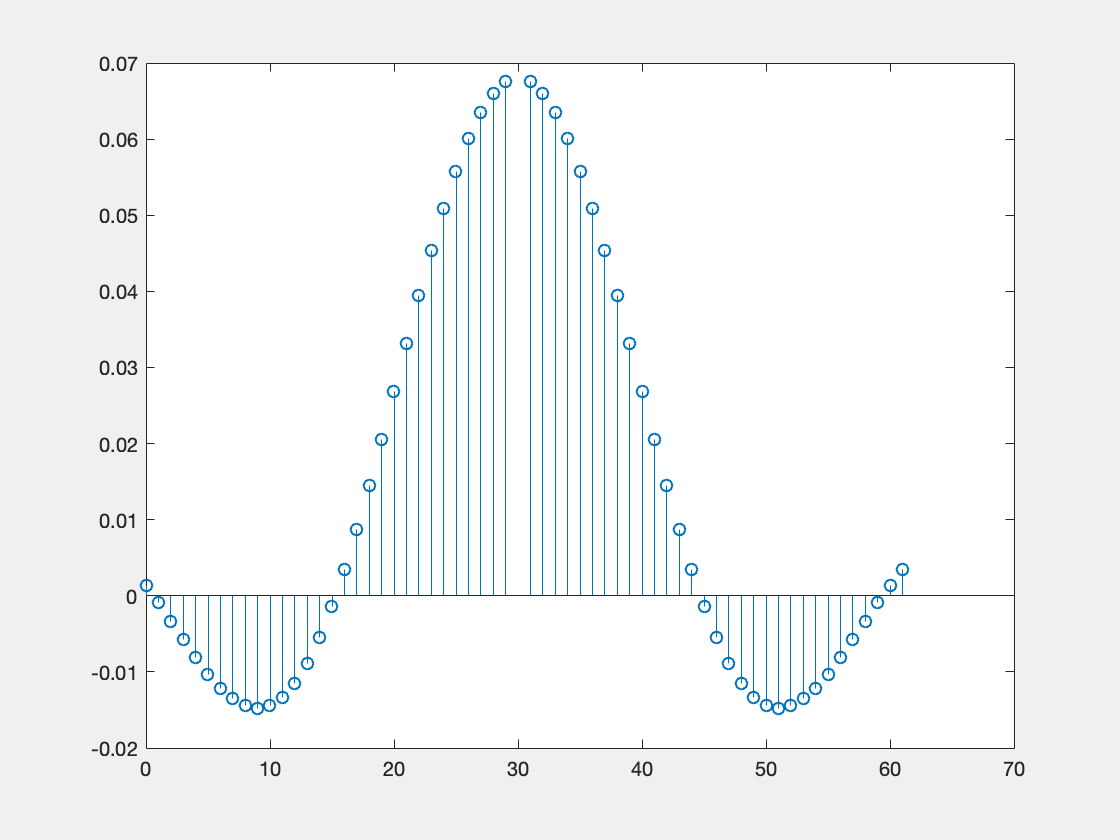

stem(n, xn)

Filter your recorded speech signal with the truncated low-pass filter and play the resulting signal.

Put your code here

lp_y = filter(xn, 1, new_y);
sound(lp_y, samplerate);

# Truncated Ideal High-Pass Filter

Create an ideal truncated low-pass filter based on the following formula


$$H(e^{j\,\omega}) = \left\{\begin{array}{ll}
1\cdot e^{-j\,\alpha\,\omega}\text{,} & \omega_c < |\omega| \le \pi \\
0\text{,} & |\omega| \le \omega_c
\end{array}$$


## Compute the Analytic Solution for the impulse response below:

Show your work using latex equations below.

Put work here:


$$h\left\lbrack n\right\rbrack =\left\lbrack \int_{w_c }^{\pi } e^{\mathrm{jw}\left(n-a\right)} \;\mathrm{dw}+\int_{-\pi }^{-w_c } e^{\mathrm{jw}\left(n-a\right)} \;\mathrm{dw}\right\rbrack ={\left\lbrack \frac{1}{2\pi \;j\left(n-a\right)}e^{\mathrm{jw}\left(n-a\right)} \right\rbrack }_{w_{c\;} }^{\pi \;} +{\left\lbrack \frac{1}{2\pi \;j\left(n-a\right)}\right\rbrack }_{-\pi \;}^{-w_c }$$



$$h\left\lbrack n\right\rbrack =\frac{1}{2\pi \;j\left(n-a\right)}\left\lbrack e^{j\pi \;\left(n-a\right)} -e^{{\mathrm{jw}}_{c\;} \left(n-a\right)} +e^{-{\mathrm{jw}}_{c\;} \left(n-a\right)} -e^{-j\pi \;\left(n-a\right)} \right\rbrack$$



$$\begin{array}{l}
h\left\lbrack n\right\rbrack =\frac{1}{2\pi \;j\left(n-a\right)}\left\lbrack e^{j\pi \;\left(n-a\right)} -e^{-j\pi \;\left(n-a\right)} -e^{{\mathrm{jw}}_{c\;} \left(n-a\right)} +e^{-{\mathrm{jw}}_{c\;} \left(n-a\right)} \right\rbrack =\frac{\mathrm{sin}\left(\pi \;\left(n-a\right)\right)}{\pi \;\left(n-a\right)}-\frac{\mathrm{sin}\left(w_c \left(n-a\right)\right)}{w_c \left(n-a\right)}\\
h\left\lbrack n\right\rbrack =\delta \left\lbrack n-a\right\rbrack -\frac{\mathrm{sin}\left(w_c \left(n-a\right)\right)}{w_{c\;} \left(n-a\right)}
\end{array}$$


Determine and plot the truncated impulse response 


$$h[n] \ \text{for} \ 0 \le n < N-1$$


using N = 61, $\alpha = 30$. Choose $\omega_c$ so that the cut-off frequency is 1500 Hz, using 44100 sample rate.

Put your code here

fs = 44100;
n = (0:61);
% cutoff frequency of 1500Hz
omegac = (2*pi*1500/fs);
a = 30;
xn = sin(pi*(n-a))./(pi*(n-a)) - sin(omegac*(n-a))./(pi*(n-a));
size(n)

ans =      1    62


size(xn)

ans =      1    62


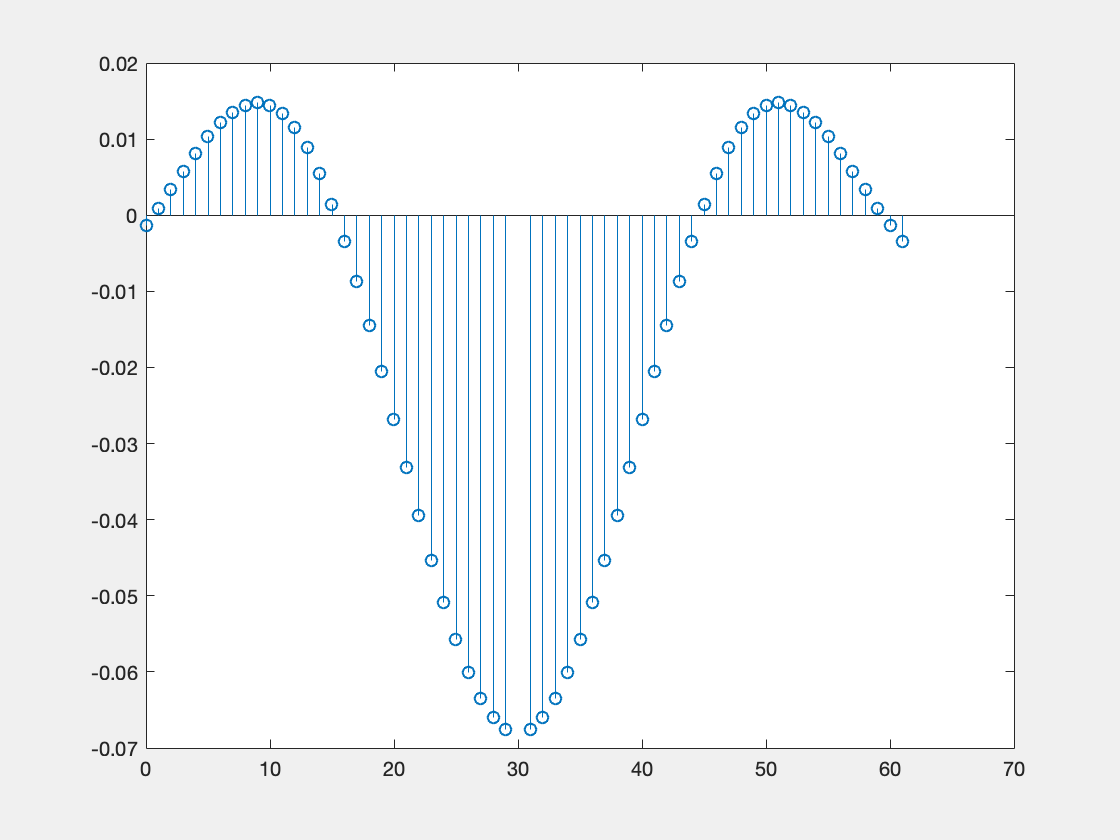

stem(n, xn)

Filter your recorded speech signal with the truncated low-pass filter and play the resulting signal.

Put your code here

hp_y = filter(xn, 1, new_y);
sound(hp_y, samplerate);

# Create a DTFT Matlab Function

Use the example code given in class to create a MATLAB function the computes the DTFT of a finite-duration signal.  The function should have the following format

function Xfq = dtft(xn, n, omega)

% xn is finite duration signal over n

% n is the sample position vector

% omega is the frequency location vector

Upload your function as part of the lab solution.

# DTFT of Window Function

Use your DTFT function to compute the DTFT of the following window functions:

Rectangular $R_{M}[n] = \left\{\begin{array}{ll}
                          1\, \text{,} & 0 \le n < M \\
                          0\, \text{,} & \text{otherwise}                         
\end{array}$

Hanning $C_{M}[n] = 0.5\left[1 - \cos\left(\frac{2\,\pi\,n}{M-1}\right)\right]R_{M}[n]$

Triangular $T_{M}[n] = \left[1- \frac{|M-1-2\,n|}{M-1}\right]R_{M}[n]$

Hamming $H_{M}[n] = \left[0.54 - 0.46\cos\left(\frac{2\,\pi\,n}{M-1}\right)\right]R_{M}[n]$

Let M vary from 10, 25, 50, 101. Normalise the DTFT by dividing by its magnitude. 

Plot the normlized DTFT as a function of M for each of the window functions. Use the subplot function.

Put your code here:

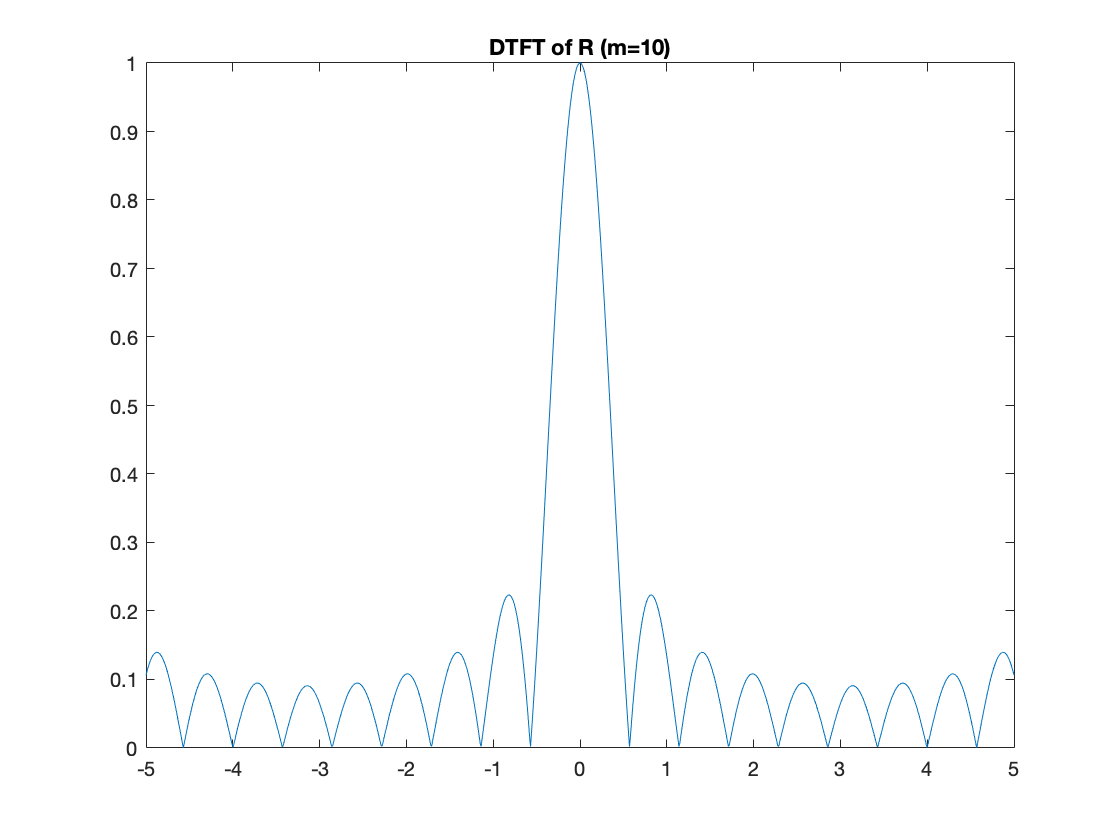

% m=10
omega=-5:0.01:5;

n_10=0:1:10;
xn_10r(1:11)=1;
xn_10c=0.5*(1-cos(2*pi*n_10/9)).*xn_10r;
xn_10t=1-abs(9-2.*n_10)/9.*xn_10r;
xn_10h=0.54-0.46*cos(2*pi*n_10/9).*xn_10r;

Xfq_10r=dtft(xn_10r,n_10,omega);
plot(omega, abs(Xfq_10r./max(abs(Xfq_10r))))
title("DTFT of R (m=10)")

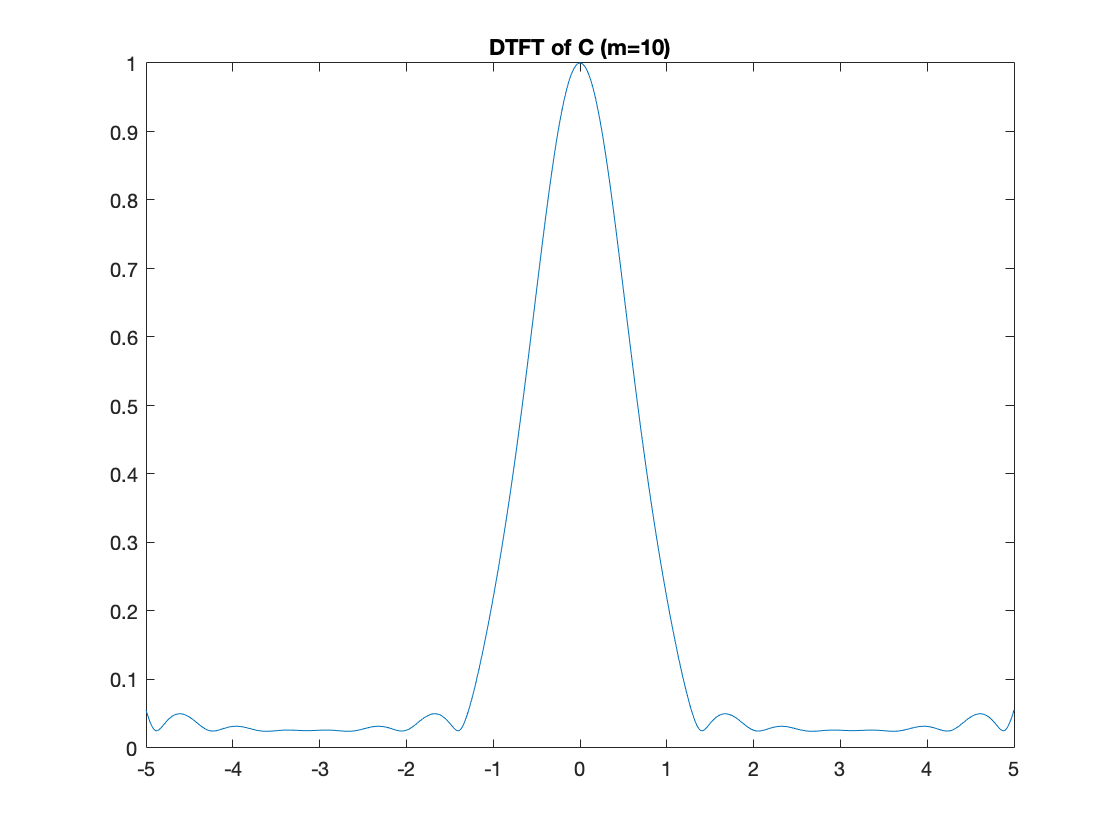

Xfq_10c=dtft(xn_10c,n_10,omega);
plot(omega, abs(Xfq_10c./max(abs(Xfq_10c))))
title("DTFT of C (m=10)")

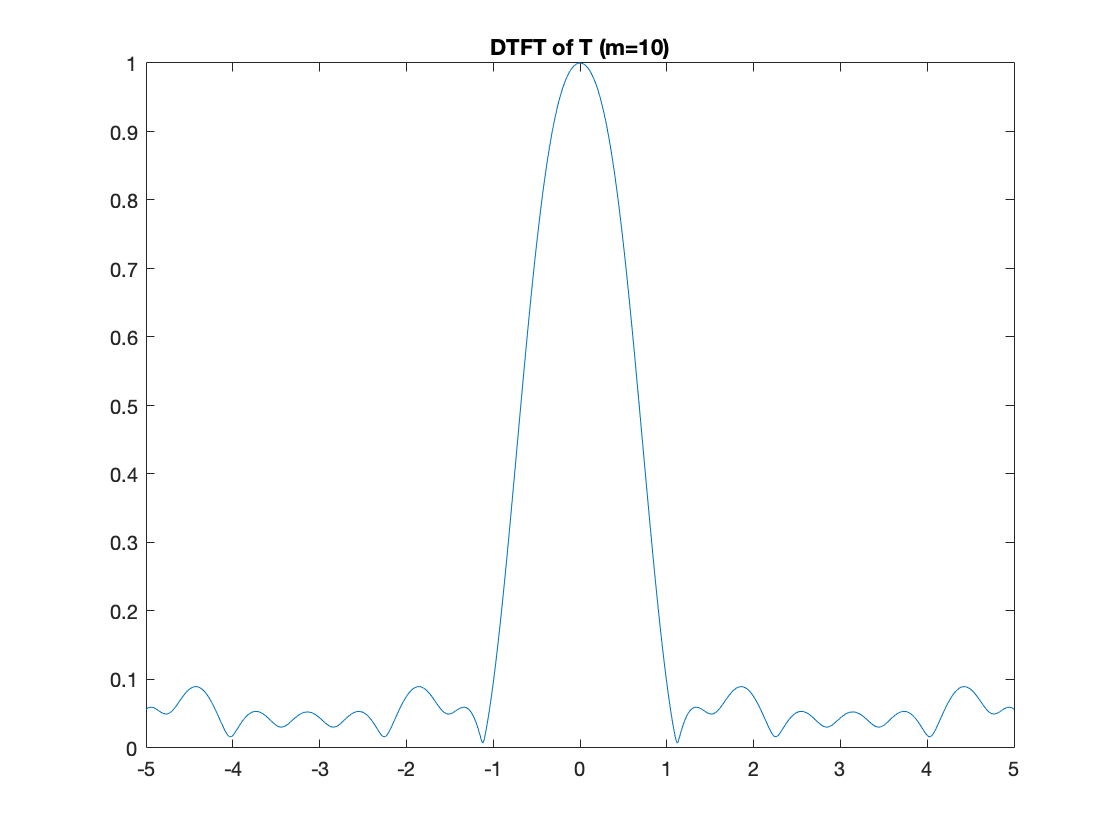

Xfq_10t=dtft(xn_10t,n_10,omega);
plot(omega, abs(Xfq_10t./max(abs(Xfq_10t))))
title("DTFT of T (m=10)")

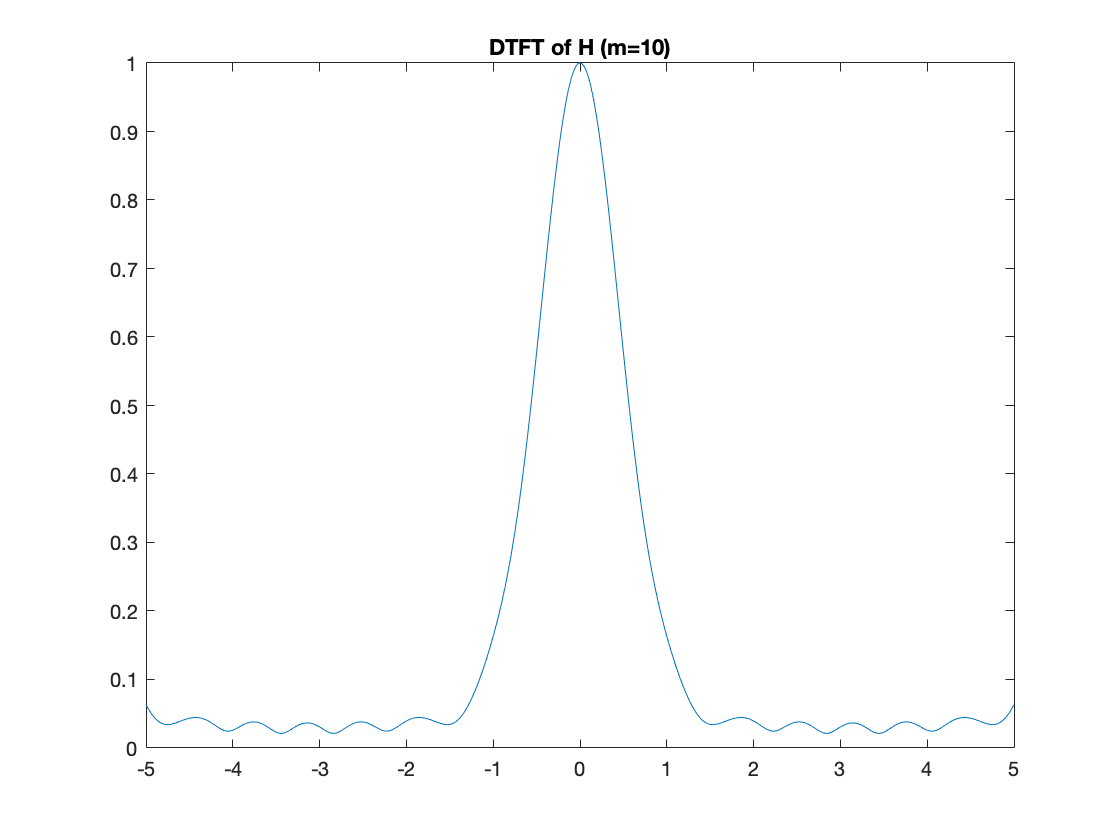

Xfq_10h=dtft(xn_10h,n_10,omega);
plot(omega, abs(Xfq_10h./max(abs(Xfq_10h))))
title("DTFT of H (m=10)")

%m=25

n_25=0:1:25;
xn_25r(1:26)=1;
xn_25c=0.5*(1-cos(2*pi/24.*n_25));
xn_25t=1-abs(24-2.*n_25)/24;
xn_25h=0.54-0.46*cos(2*pi*n_25/24);

Xfq_25r=dtft(xn_25r,n_25,omega);
plot(omega,Xfq_25r/abs(Xfq_25r))

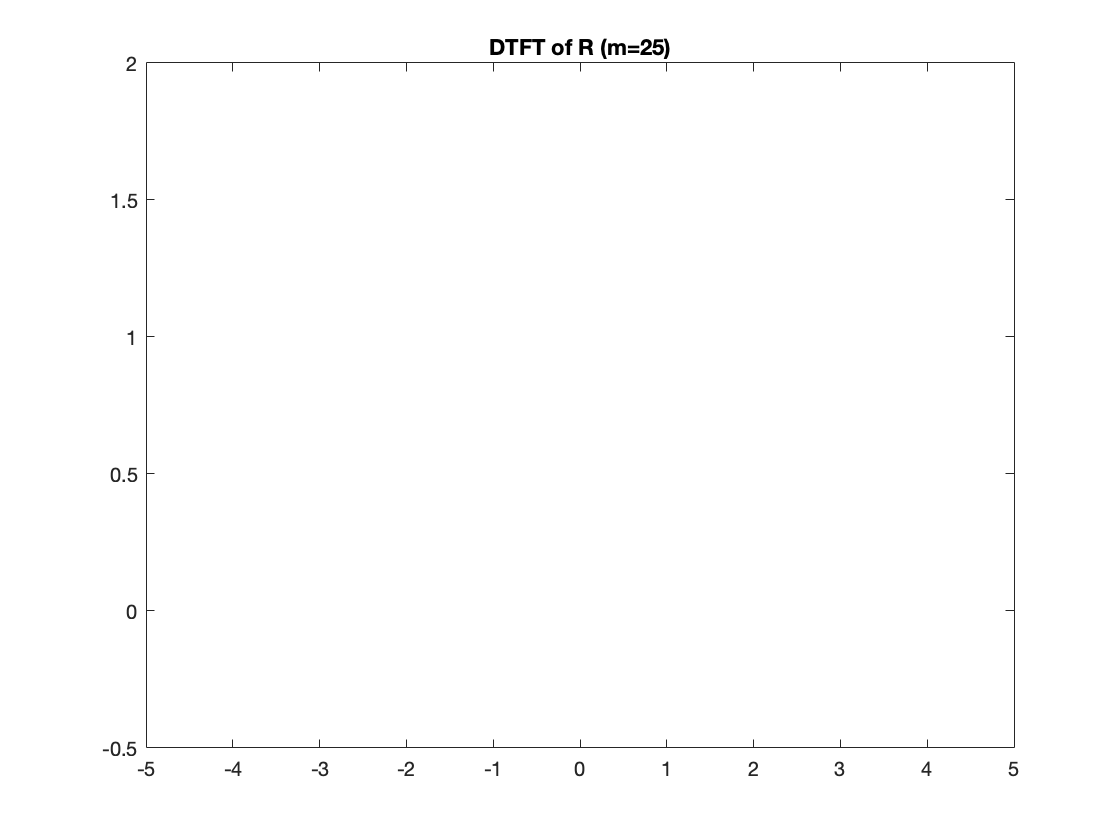

title("DTFT of R (m=25)")

Xfq_25c=dtft(xn_25c,n_25,omega);
plot(omega,Xfq_25c/abs(Xfq_25c))

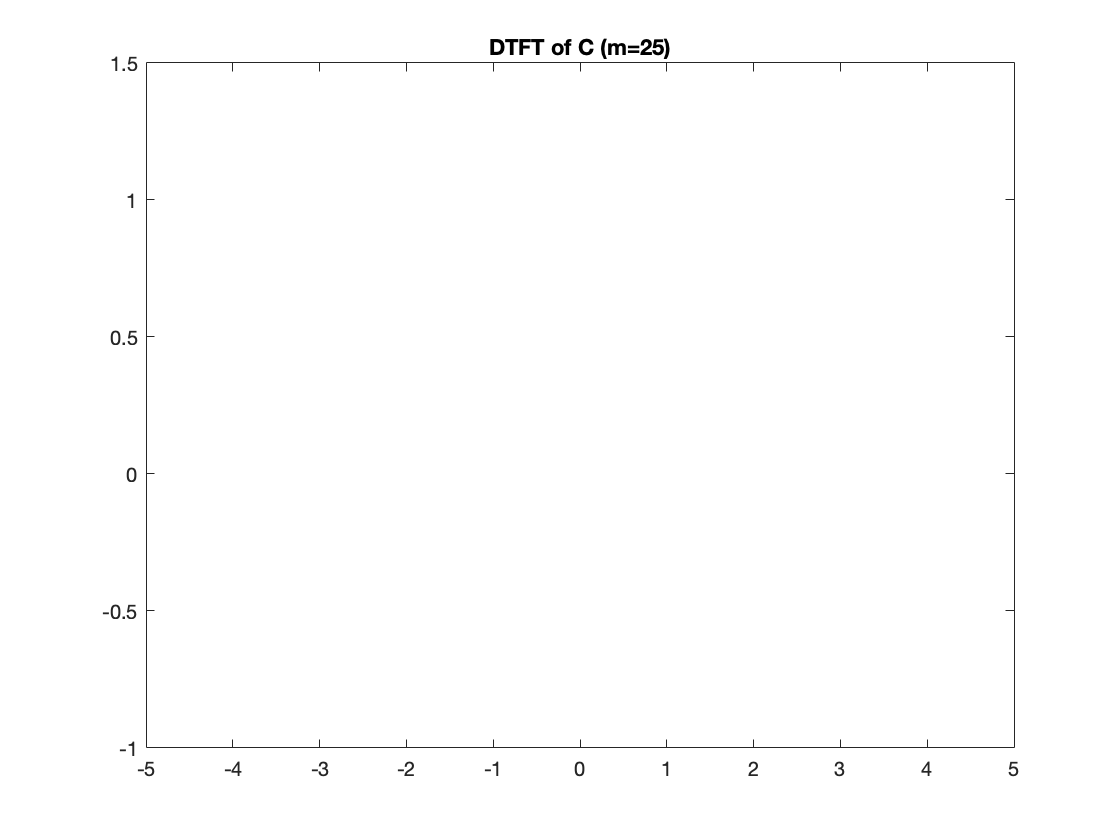

title("DTFT of C (m=25)")

Xfq_25t=dtft(xn_25t,n_25,omega);
plot(omega,Xfq_25t/abs(Xfq_25t))

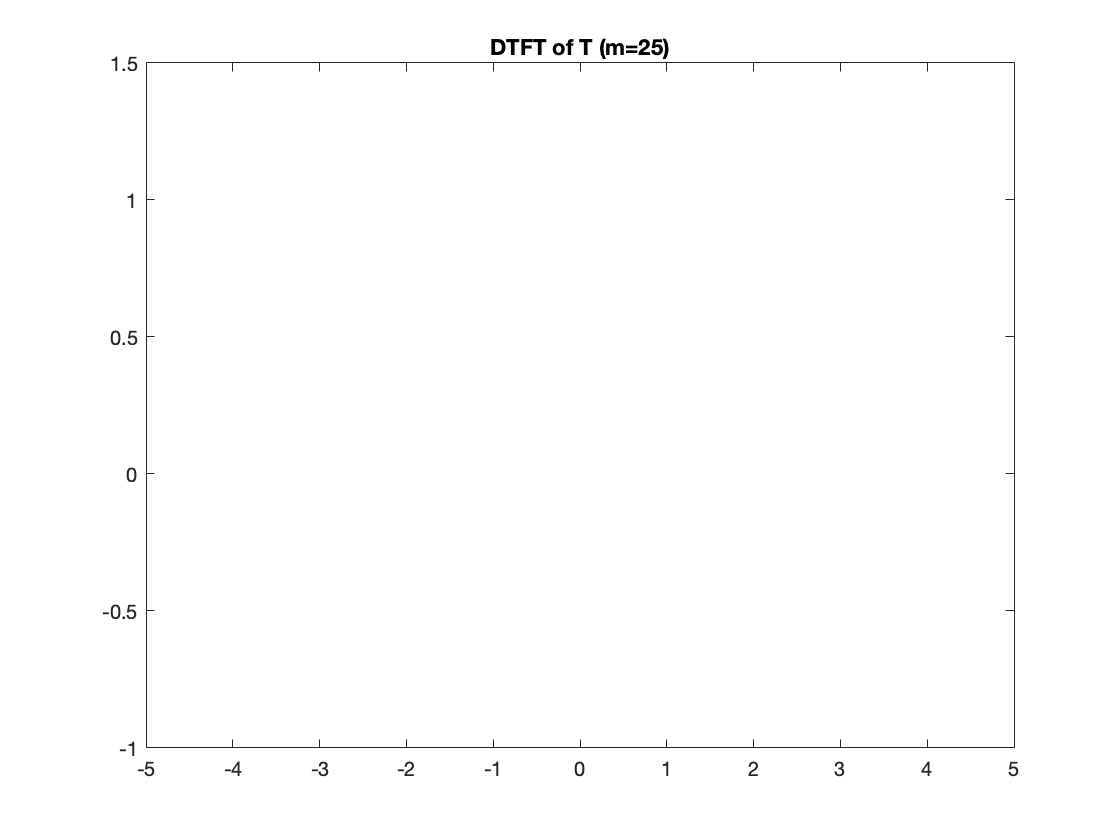

title("DTFT of T (m=25)")

Xfq_25h=dtft(xn_25h,n_25,omega);
plot(omega,Xfq_25h/abs(Xfq_25h))

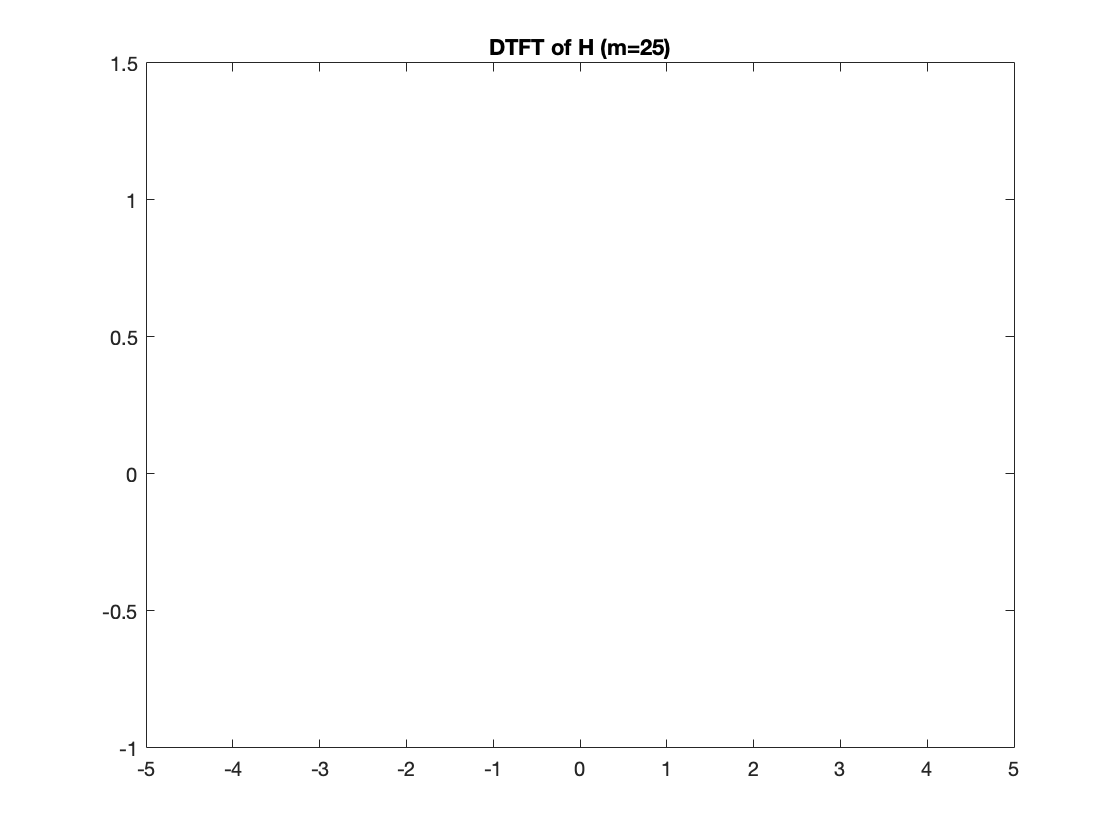

title("DTFT of H (m=25)")


%m=50
n_50=0:1:50;
xn_50r(1:51)=1;
xn_50c=0.5*(1-cos(2*pi/49.*n_50));
xn_50t=1-abs(49-2.*n_50)/49;
xn_50h=0.54-0.46*cos(2*pi*n_50/49);

Xfq_50r=dtft(xn_50r,n_50,omega);
plot(omega,Xfq_50r/abs(Xfq_50r))

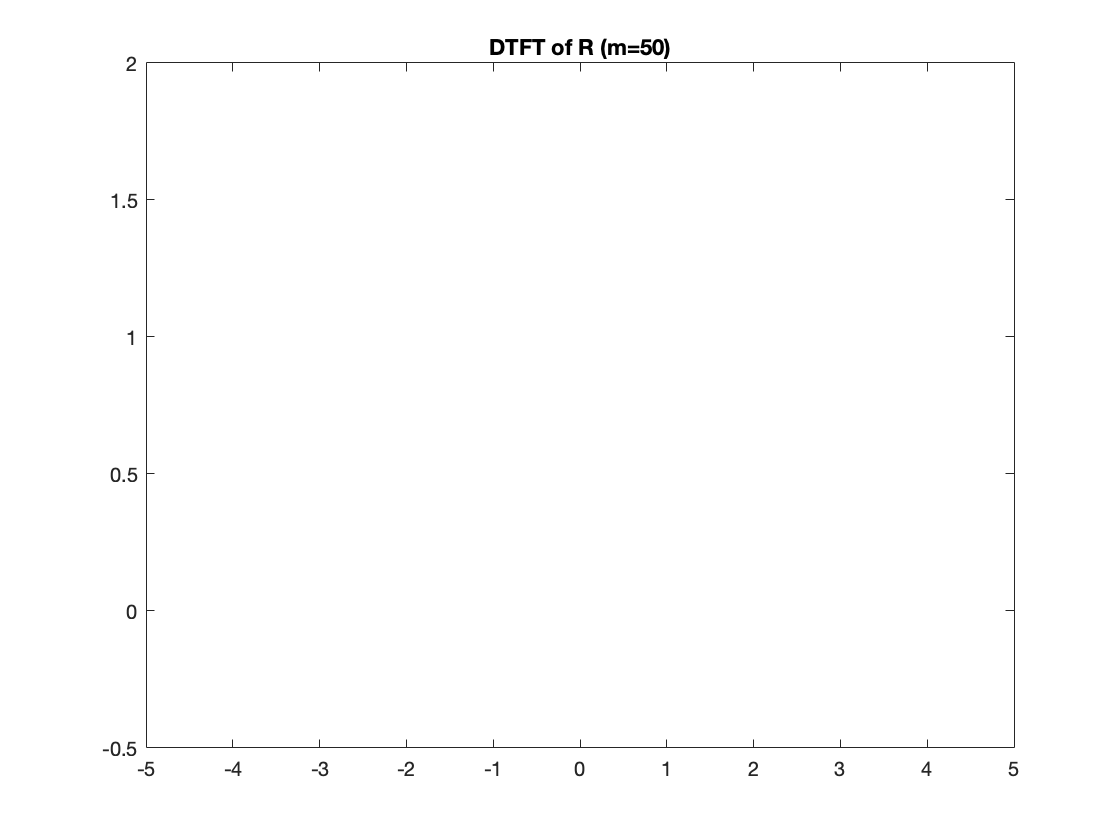

title("DTFT of R (m=50)")

Xfq_50c=dtft(xn_50c,n_50,omega);
plot(omega,Xfq_50c/abs(Xfq_50c))

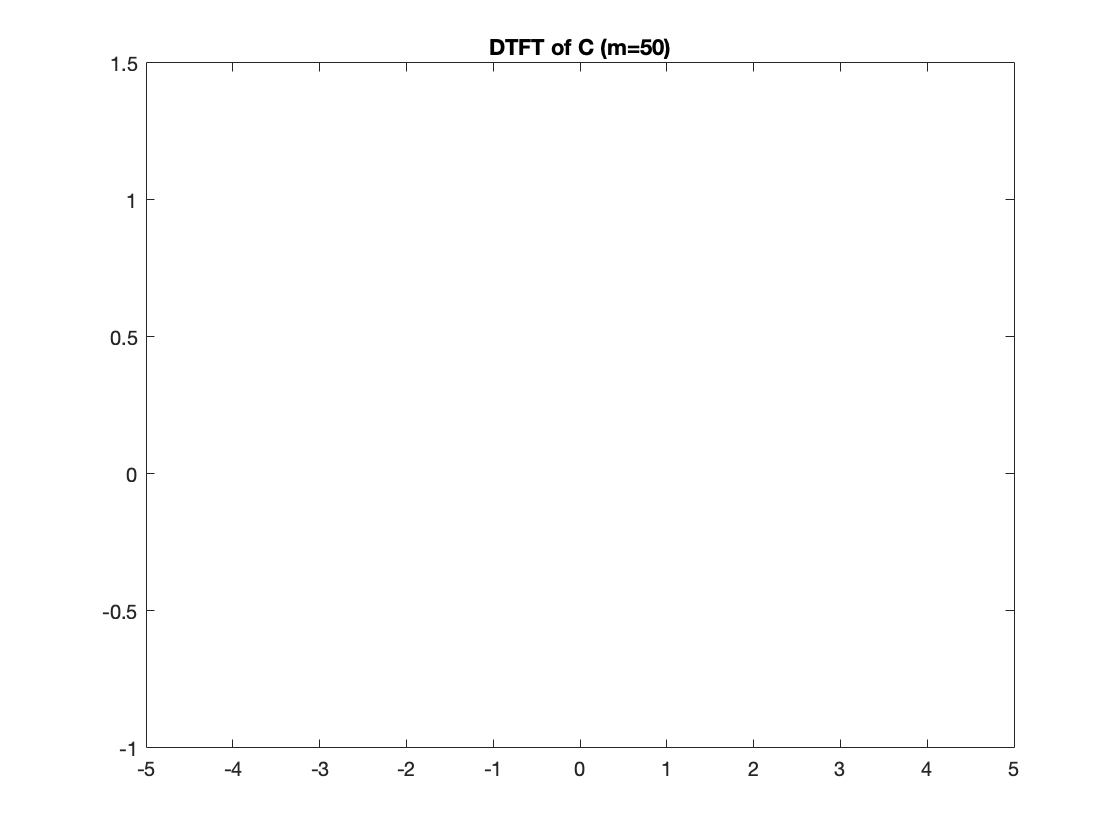

title("DTFT of C (m=50)")

Xfq_50t=dtft(xn_50t,n_50,omega);
plot(omega,Xfq_50t/abs(Xfq_50t))

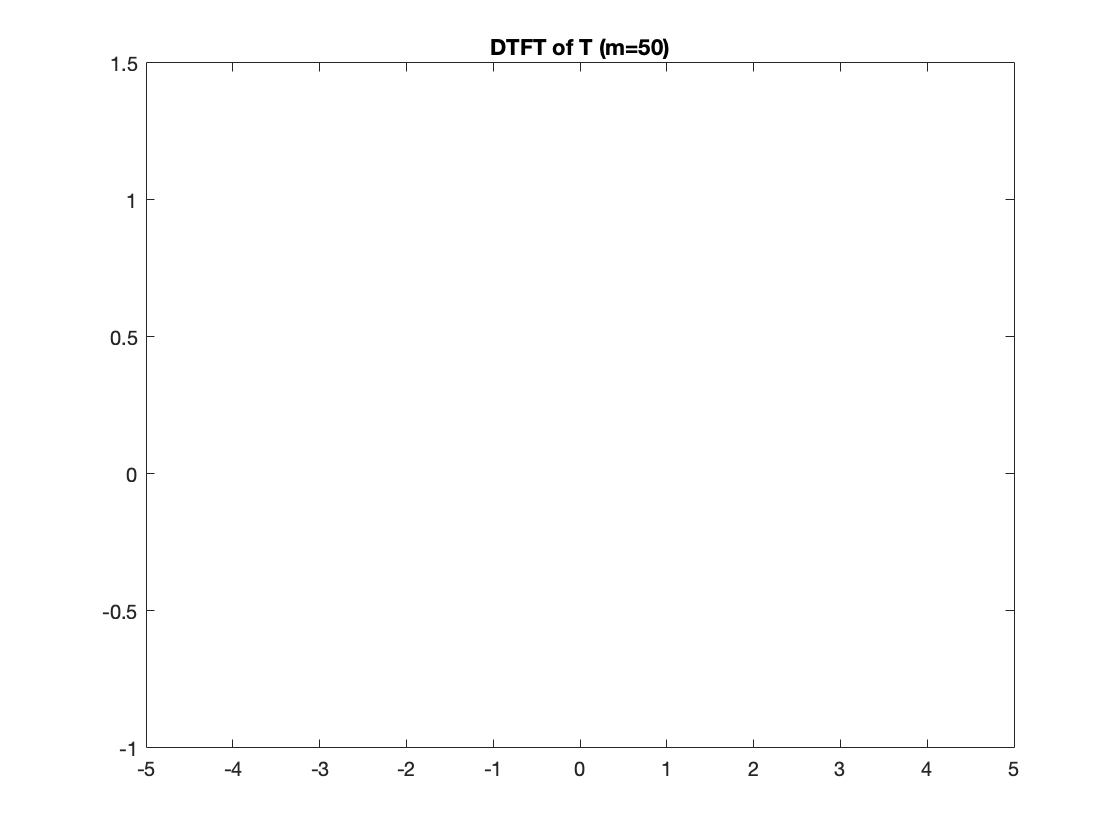

title("DTFT of T (m=50)")

Xfq_50h=dtft(xn_50h,n_50,omega);
plot(omega,Xfq_50h/abs(Xfq_50h))

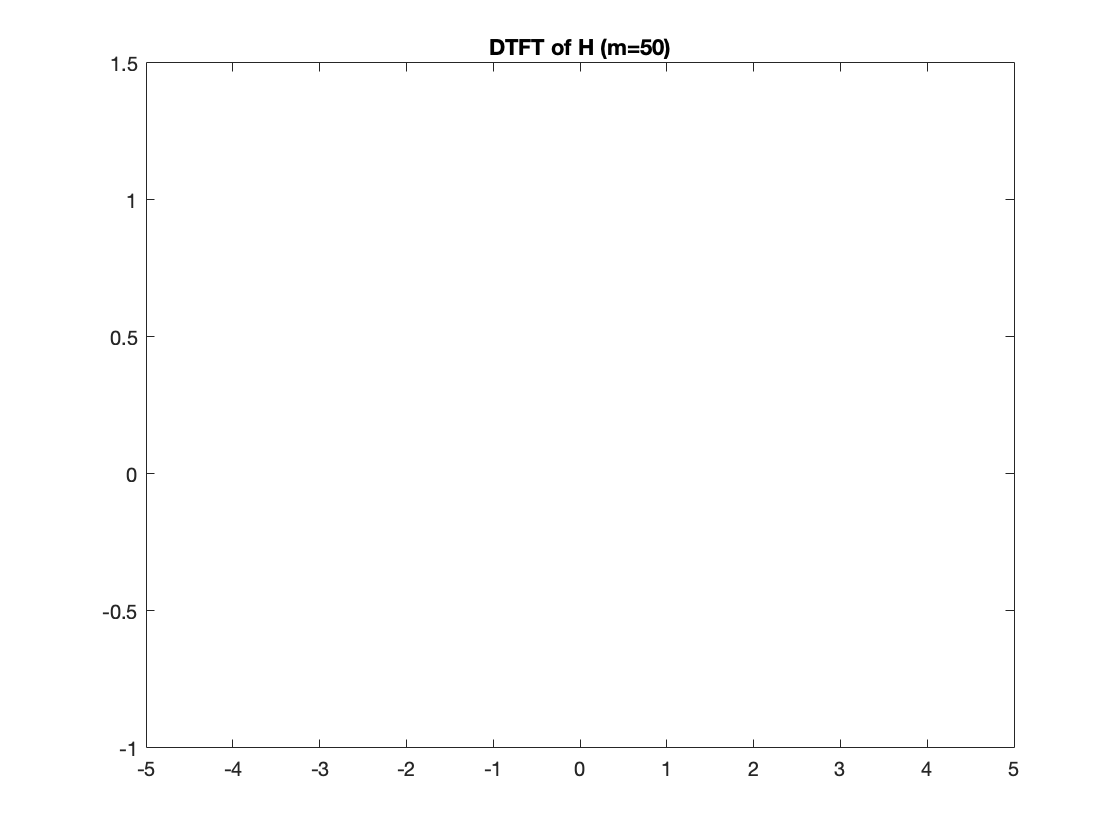

title("DTFT of H (m=50)")

%m=101
n_101=0:1:101;
xn_101r(1:102)=1;
xn_101c=0.5*(1-cos(2*pi/100.*n_101));
xn_101t=1-abs(100-2.*n_101)/100;
xn_101h=0.54-0.46*cos(2*pi*n_101/100);

Xfq_101r=dtft(xn_101r,n_101,omega);
plot(omega,Xfq_101r/abs(Xfq_101r))

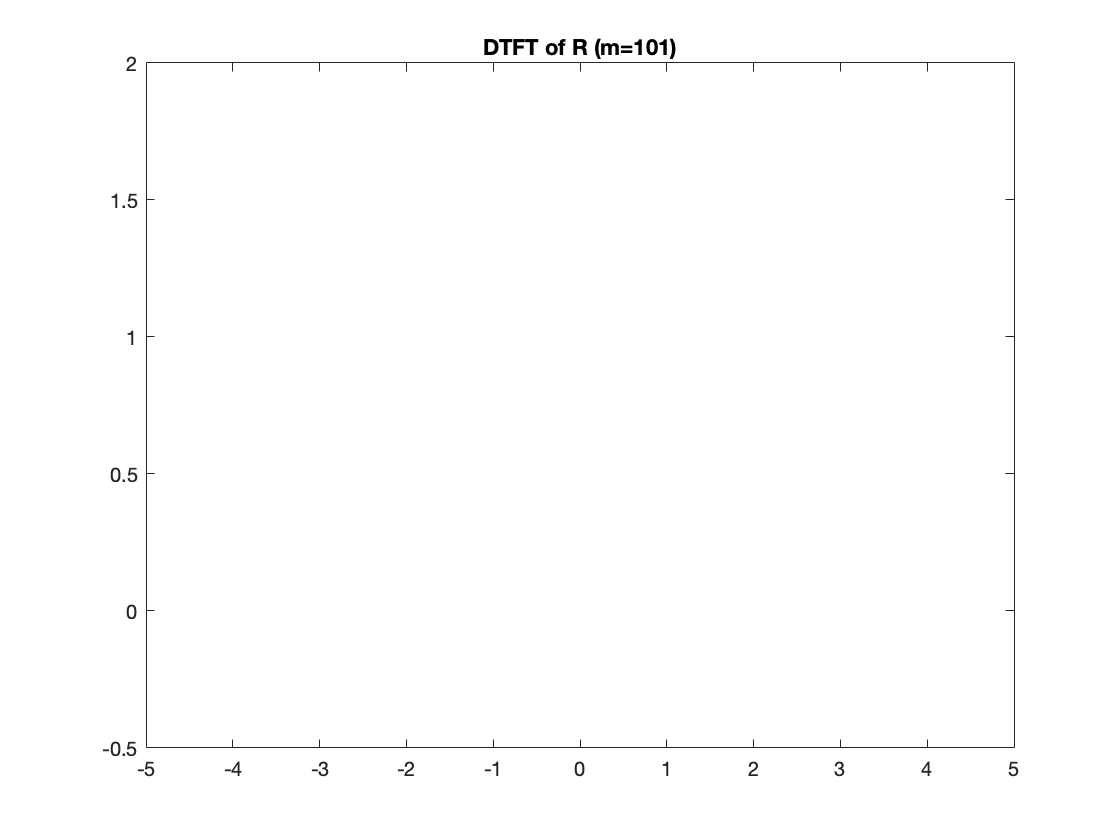

title("DTFT of R (m=101)")

Xfq_101c=dtft(xn_101c,n_101,omega);
plot(omega,Xfq_101c/abs(Xfq_101c))

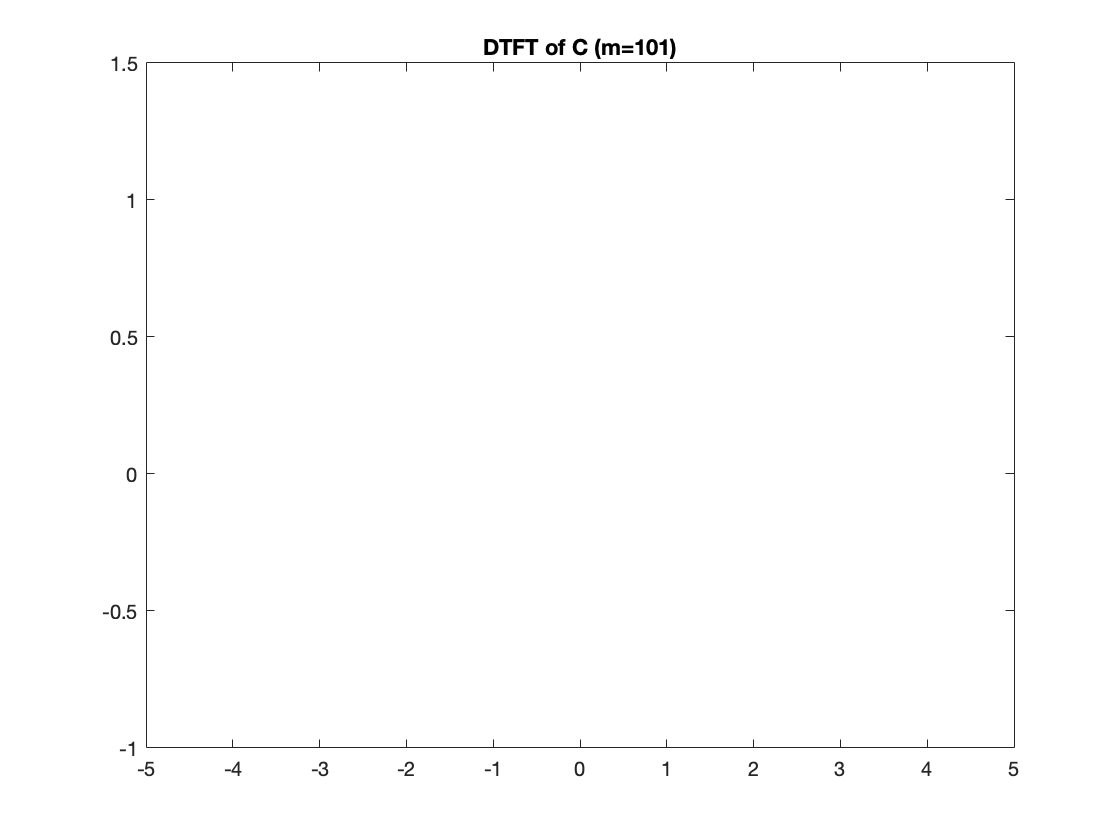

title("DTFT of C (m=101)")

Xfq_101t=dtft(xn_101t,n_101,omega);
plot(omega,Xfq_101t/abs(Xfq_101t))

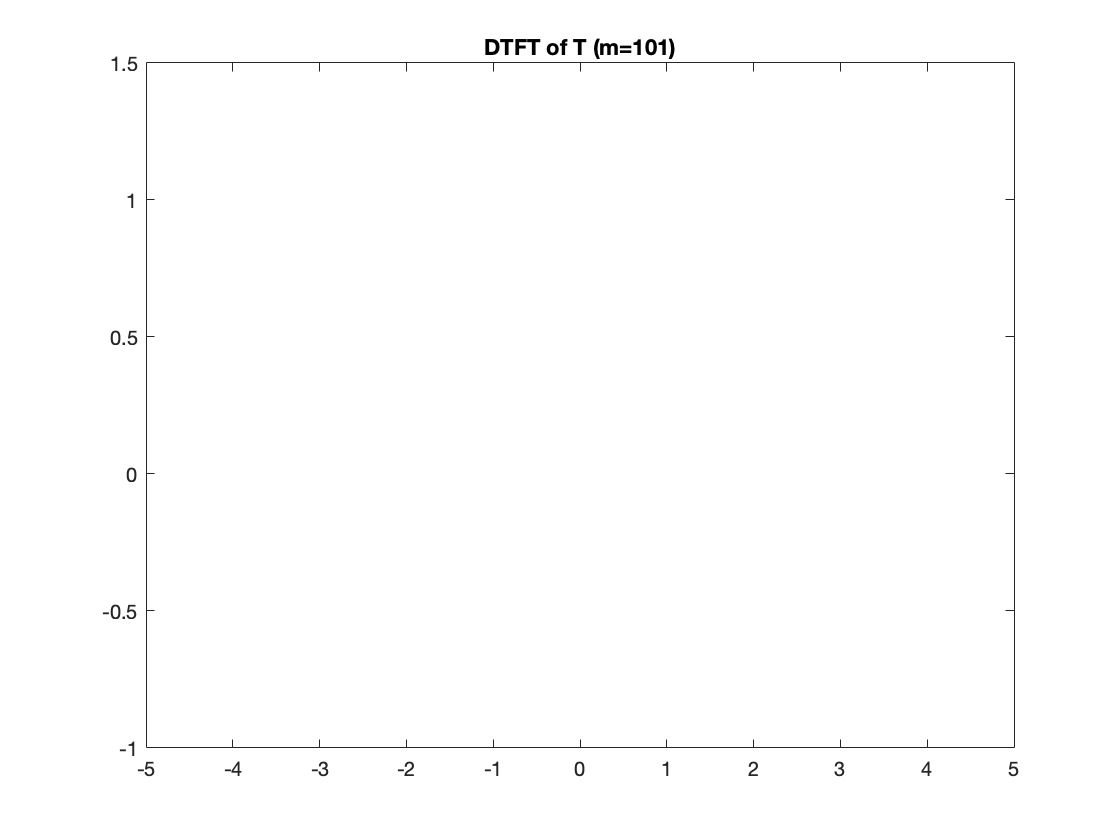

title("DTFT of T (m=101)")

Xfq_101h=dtft(xn_101h,n_101,omega);
plot(omega,Xfq_101h/abs(Xfq_101h))

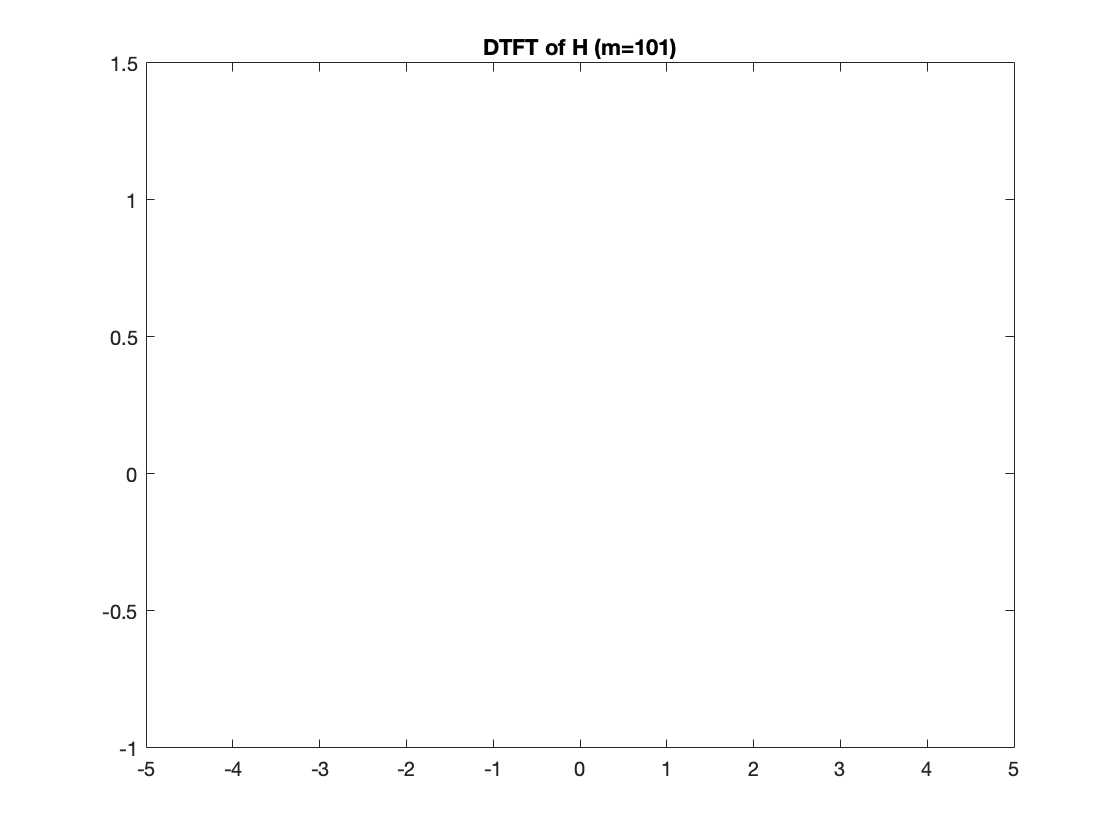

title("DTFT of H (m=101)")

# Convolution and Deconvolution as Polynomial Multiplication and Division

Multiply the following two polynomials together using the conv_m.m Matlab function.


$$X_{1}(z) = z + 2 + 3z^{-1}$$



$$X_2(z) = 2z^{2}  + 4z + 3 + 5z^{-1}$$



$$X_3(z) = X_1(z) \cdot X_2(z)$$


Put your code here:

n1=-1:1;
n2=-1:2;
x1=[1 2 3];
x2=[2 4 3 5];
[y,ny]=conv_m(x1,n1,x2,n2);
y

y =      2     8    17    23    19    15


Write down the polynomial $X_3(z)$ using a latex equation below:

Put your answer here:


$$X(z) = 2z^{3}+8z^{2}+13z+15+13z^{-1}+15z^{-2}$$


Divide the following two polynomials using the deconv_m.m Matlab function.


$$X(z) = \frac{z^{2} + z + 1 + z^{-1}+z^{-2} + z^{-3}}{z + 2 + z^{-1}}$$


Put your code here:

u=[1 1 1 1 1 1];
un=-3:2;
v=[1 2 1 0 0];
vn=-1:1;
[q,qn,r,rn]=deconv_m(u,un,v ,vn);
q, r, qn, rn

q =      1    -1


r =      0     0     2     2     1     1


qn =     -2    -1


rn =     -3    -2    -1     0     1     2


Write down the polynomial $X(z)$ using a latex equation below:

Put your answer here: 

Divide the remainder by quotient


$$X(z) =(z-1)(z+2+z^{-1})+2+2z^{-1}+z^{-2}+z^{-3} $$


# Second-order System

The sequence 


$$x[n] = A_{c} (r)^n \cos(\pi\,\nu_{0}\,n)\,u(n) + A_{s} (r)^n \sin(\pi \, \nu_{0}\,n)\,u(n)$$


corresponds to the following Z-Transform


$$X(z) = \frac{b_0 + b_1z^{-1}}{1+a_1z^{-1}+a_2z^{-2}} \ \text{,} \ |z| > |r|$$


where 


$$b_0 = A_c \ \text{;} \ b_1 = r\left[A_s \sin(\pi\,\nu_{0}) - A_c \cos(\pi\,\nu_{0})\right] \ \text{;} \ a_1 = -2r\,\cos(\pi\,\nu_{0}) \ \text{;} \ a_2 = r^2 \ \text{.}$$


Determine the signal parameters $A_c \, \text{,} \ A_s \, \text{,} \ r \, \text{,} \ \nu_{0}$ in terms of the rational function parameters $b_0 \, \text{,} \ b_1 \, \text{,} \ a_1 \, \text{,} \ a_2$ . Write a MATLAB function invCCPP that computes the signal parameters from the rational function parameters. 

You function shoiuld have the form:

function [Ac, As, r, v0] = invCCPP(b0, b1, a1, a2)

Upload this function along with your solution mlx file.

Consider the Z-Transform


$$X(z) = \frac{-2 +5.65z^{-1} -2.88z^{-2}}{1 - 0.1z^{-1} + 0.09 z^{-2} +0.648 z^{-3}}$$


By clever use of the residuez function, express $X(z)$ as:


$$X(z) = \frac{( ) + ()z^{-1}}{1+()z^{-1} + ()z^{-2}} + \frac{()}{1+()z^-1}$$


Use your invCCPP function to determine the causal sequence x[n] corresponding to $X(z)$such that the sequence has no complex numbers in it.

Put your matlab code here:

b=[2 5.65 -2.88];
a=[1 -0.1 0.09 0.648];
[R,p,C]=residuez([-2 5.65 -2.88],[1 -0.1 0.09 0.648])

R =    1.0000 - 0.8660i
   1.0000 + 0.8660i
  -4.0000 + 0.0000i


p =    0.4500 + 0.7794i
   0.4500 - 0.7794i
  -0.8000 + 0.0000i



C =

     []



[bn,an]=residuez(R(1:2),p(1:2),C);
[Ac,As,r,v0]=invCCPP(bn(1),bn(2),an(2),an(3))

Ac = 2.0000

As = 1.7321

r = 0.9000

v0 = 0.3333

Write down the sequence x[n] using latex below:


$$x[n] = 2*0.9^{n}cos(v_0\pi )u(n)+1.7321*0.9^{n}sin(\pi v_0n)u(n)-4(0.8)^{n}u(n)$$
